clc;
clear;
close all;
tic
%% Problem Definition

problem.CostFunction = @(x) ObjectiveFunc(x);
problem.nVar = 50;
last = 25;

eliteCount = 2; % number of elite chromosomes

global fm

fm = 0;

%% GA Parameters

params.MaxIt = 500;
params.nPop = 50;

params.beta = 1;
params.pC = 1;
params.mu = 0.05;



% Problem
    CostFunction = problem.CostFunction;
    nVar = problem.nVar;
    
    % Params
    MaxIt = params.MaxIt;
    nPop = params.nPop;
    beta = params.beta;
    pC = params.pC;     % Percentage of Children for Crossover
    % nC is no. of Offspring, round is used to roundoff to the nearest
    % integer, /2)*2 is done to get an even no. of offspring
    nC = round(pC*nPop/2)*2;
    mu = params.mu;
    
    % Template for Empty Individuals
    % We use these template of empty arrays and fill them in Initialization 
    empty_individual.Position = [];
    empty_individual.Cost = [];
    
    % Best Solution Ever Found
    bestsol.Cost = 0;
    
    % Initialization
    % Repmat repeat everything in matlab, it is a repeating matrix
    pop = repmat(empty_individual, nPop, 1);

%     [s1] = RandStream.create('mlfg6331_64','NumStreams',1);        
      s1 = rng(123,'mlfg6331_64');

    % In this For loop we are filling the empty arrays
    for i = 1:nPop
        
        % Generate Random Solution    

        
        a = zeros(1, last);        
        b = zeros(1, last);
        k = 1;
        n = 2;         % 0, 1 or 2
        a(randperm(last, k)) = 1;
        b(randperm(last, n)) = 1;  % Elements at n indices of 5 set o 1
        pop(i).Position = [a, b];
        x = [a, b];
        
        % Evaluate Solution
        pop(i).Cost = CostFunction(pop(i).Position);

        % Merge and Sort Populations
        pop = SortPopulation(pop);
         struct2table(pop);
         t=sortrows(struct2table(pop), 'Cost','descend');
         s = table2struct(t);

                                
        % Remove Extra Individuals
        pop = s;
        
        % Compare Solution to Best Solution Ever Found
        if pop(i).Cost > bestsol.Cost
            bestsol = pop(i);
        end
        
    end
   
    % Best Cost of Iterations
    bestcost = nan(MaxIt, 1);
    
    % Main Loop
      avgm = 0;
      TPop=[];
      Tavg=[];

    for it = 1:MaxIt

        TPop=[TPop ;pop.Cost];

        fm=pop(end).Cost;

         % Select the elite chromosomes
         elite = pop(1:eliteCount,:);

        pop = [elite; pop];
        pop = pop(1:nPop,:);
        
        % Selection Probabilities
        c = [pop.Cost];
        avgc = mean(c);
        if avgc ~= 0       % ~= means not equal to 
            c = c/avgc;
        end
        probs = exp(-beta*c);
        
        % Initialize Offsprings Population
        % popc is the population of children
        popc = repmat(empty_individual, nC/2, 2);
        
        % Crossover
        for k = 1:nC/2
            
            % Select Parents
            p1 = pop(RouletteWheelSelection(probs));
            p2 = pop(RouletteWheelSelection(probs));
            
            % Perform Crossover
            [popc(k, 1).Position, popc(k, 2).Position] = ...
                DoublePointCrossover(p1.Position, p2.Position);
        end
             
        % Evaluate Solution
        for i=1:2
             popc(1,i).Cost = CostFunction(popc(1,i).Position);
            
        end
        
        % Convert popc to Single-Column Matrix
        popc = popc(:);
       
        
        % Mutation
        for l = 1:nC
            
            % Perform Mutation
            popc(l).Position = Mutate(popc(l).Position, mu);
            
            % Evaluation
            popc(l).Cost = CostFunction(popc(l).Position);
            
            % Compare Solution to Best Solution Ever Found
            if popc(l).Cost > bestsol.Cost
                bestsol = popc(l);
            end
            
        end
        
        % Merge and Sort Populations
        pop = SortPopulation([pop, popc]);
         struct2table(pop);
         tc=sortrows(struct2table(pop), 'Cost','descend');
         sc = table2struct(tc);
        
        % Remove Extra Individuals
        pop = sc(1:nPop,:);

                
        % Update Best Cost of Iteration
        bestcost(it) = bestsol.Cost;
        
        % Display Itertion Information
        disp(['Iteration ' num2str(it) ': Best Cost = ' num2str(bestcost(it))]);

        Pop_Table = TPop';

        % Stopping Criteria
          z = [pop.Cost];
          avg = mean(z);
          diff = avg - avgm;
          ratio = abs(diff/avg);
          if ratio < 10^(-5)
              break
          end
          avgm = avg;

          Tavg = [Tavg; avg];
          Avg_Table = Tavg';
      end

Iteration 1: Best Cost = 46.453
Iteration 2: Best Cost = 46.453
Iteration 3: Best Cost = 46.453
Iteration 4: Best Cost = 46.453
Iteration 5: Best Cost = 54.3265
Iteration 6: Best Cost = 54.3265
Iteration 7: Best Cost = 58.6382
Iteration 8: Best Cost = 59.9865
Iteration 9: Best Cost = 59.9865
Iteration 10: Best Cost = 62.9834
Iteration 11: Best Cost = 64.3794
Iteration 12: Best Cost = 64.3794
Iteration 13: Best Cost = 64.6806
Iteration 14: Best Cost = 68.0727
Iteration 15: Best Cost = 68.6706
Iteration 16: Best Cost = 76.2573
Iteration 17: Best Cost = 76.2573
Iteration 18: Best Cost = 81.0121
Iteration 19: Best Cost = 81.0121
Iteration 20: Best Cost = 81.0121
Iteration 21: Best Cost = 81.958
Iteration 22: Best Cost = 83.8979
Iteration 23: Best Cost = 83.8979
Iteration 24: Best Cost = 86.5732
Iteration 25: Best Cost = 86.5732
Iteration 26: Best Cost = 86.5732
Iteration 27: Best Cost = 88.2249
Iteration 28: Best Cost = 89.6366
Iteration 29: Best Cost = 89.6366
Iteration 30: Best Cost = 89

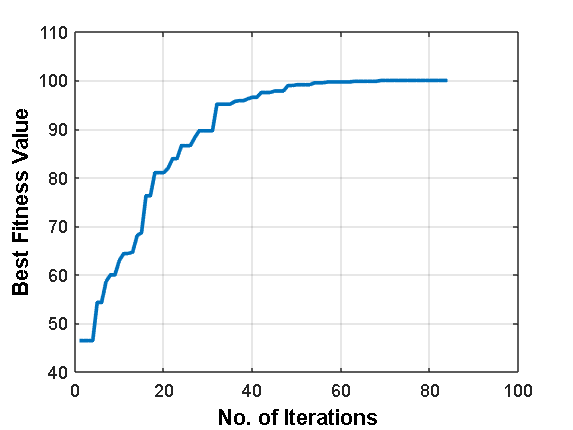

    
    
    % Results
    out.pop = pop;
    out.bestsol = bestsol;
    out.bestcost = bestcost;

    figure;
    plot(out.bestcost, 'LineWidth', 2);
    xlabel('No. of Iterations','FontSize',12,...
       'FontWeight','bold','Color','k');
    ylabel('Best Fitness Value','FontSize',12,...
       'FontWeight','bold','Color','k');
    grid on;

    toc

Elapsed time is 7.654728 seconds.
